**Visualizing the Patterns for Digits 0 through 6 (I & II)**

Before moving forward we will first visualize each pattern, 0 through 6 that we will hope to learn through the autoassociative memory.

First we construct an array of 1's and -1's to represent each digit's pixels in a 6x5 grid:

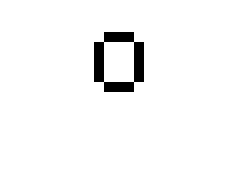

zero = [[-1 1 1 1 -1];...
        [1 -1 -1 -1 1];...
        [1 -1 -1 -1 1];...
        [1 -1 -1 -1 1];...
        [1 -1 -1 -1 1];...
        [-1 1 1 1 -1]];
% Negate the array to have the number be black in a white background.
imshow(-1*zero, [], 'InitialMagnification', 1000);

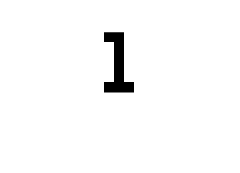

one = [[-1 1 1 -1 -1];...
       [-1 -1 1 -1 -1];...
       [-1 -1 1 -1 -1];...
       [-1 -1 1 -1 -1];...
       [-1 -1 1 -1 -1];...
       [-1 1 1 1 -1]];
imshow(-1*one, [], 'InitialMagnification', 1000);

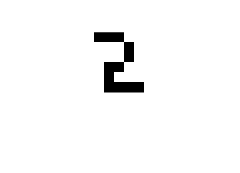

two = [[1 1 1 -1 -1];...
       [-1 -1 -1 1 -1];...
       [-1 -1 -1 1 -1];...
       [-1 1 1 -1 -1];...
       [-1 1 -1 -1 -1];...
       [-1 1 1 1 1]];
imshow(-1*two, [], 'InitialMagnification', 1000);

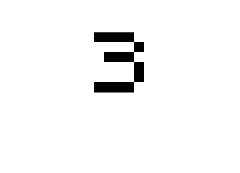

three = [[1 1 1 1 -1];...
       [-1 -1 -1 -1 1];...
       [-1 1 1 1 -1];...
       [-1 -1 -1 -1 1];...
       [-1 -1 -1 -1 1];...
       [1 1 1 1 -1]];
imshow(-1*three, [], 'InitialMagnification', 1000);

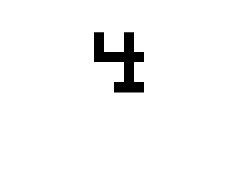

four = [[1 -1 -1 1 -1];...
       [1 -1 -1 1 -1];...
       [1 1 1 1 1];...
       [-1 -1 -1 1 -1];...
       [-1 -1 -1 1 -1];...
       [-1 -1 1 1 1]];
imshow(-1*four, [], 'InitialMagnification', 1000);

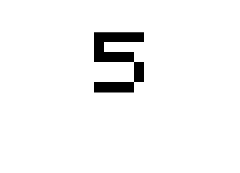

five = [[1 1 1 1 1];...
       [1 -1 -1 -1 -1];...
       [1 1 1 1 -1];...
       [-1 -1 -1 -1 1];...
       [-1 -1 -1 -1 1];...
       [1 1 1 1 -1]];
imshow(-1*five, [], 'InitialMagnification', 1000);

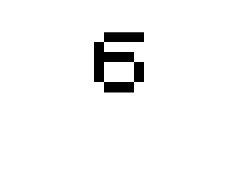

six = [[-1 1 1 1 1];...
       [1 -1 -1 -1 -1];...
       [1 1 1 1 -1];...
       [1 -1 -1 -1 1];...
       [1 -1 -1 -1 1];...
       [-1 1 1 1 -1]];
imshow(-1*six, [], 'InitialMagnification', 1000);

**Running the Experiment using Hebb's Rule (I):**

We will run the experiment as specified in the problem statement. We will use a helper function called 'mutate' that will help us randomly change any given number of pixels in a specified pattern:

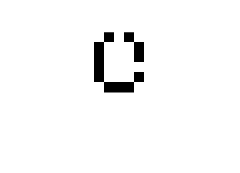

imshow(-1*mutate(2, zero), [], 'InitialMagnification', 1000);

Next we will carry out the experiment as explained. For any subsequence of [0, 1] through [0, 1, 2, 3, 4, 5, 6] we will have to do the following:

- Train a network on the given input pattern using Hebb's rule.

- Repeat for 2, 4 and 6 mutations:

-     Repeat 10 times:

-         Feed the mutated patterns into the trained network.

-         Record the percentage of times the network perfectly reconstructs the original pattern.

In order to train the network and remove redundant code, here we will use another helper function called 'hebb' that returns the weights of a network trained on list of input patterns using Hebb's Rule:

patterns = cat(3, zero, one, two, three, four, five, six);
% weights for zero and one
weights = hebb(patterns(:,:,1:2));
% feed an input into the network to verify the results
output = hardlims(weights*reshape(zero, [30, 1]));
imshow(-1*reshape(output, [6, 5]), [], 'InitialMagnification', 1000);

And now the main loop of the experiment:

% Keep three histories, for 2, 4 and 6 mutations each.
h2_hebb = [];
h4_hebb = [];
h6_hebb = [];
num_mutations = [2, 4, 6];
% for [0, 1] through [0, 1, ..., 6]
for i=2:7
    train_data = patterns(:,:,1:i);
    weights = hebb(train_data);
    % for a 2, 4 and 6 mutations
    for nm=num_mutations
        passes = 0;
        total = 10*size(train_data, 3);
        % perform 10 experiments, i.e., mutate 'nm' pixels from each input
        % pattern, then feed it into the network and compare the output
        % with the original data.
        for j=1:10
            % for each input pattern
            for l=1:size(train_data, 3)
                % do mutation
                test = mutate(nm, squeeze(train_data(:,:,l)));
                % calculate output
                output = hardlims(weights*reshape(test, [30, 1]));
                % reshape target into a [30, 1] vector
                target = reshape(train_data(:,:,l), [30, 1]);
                % compare target and output
                if isequal(target, output)
                    passes = passes + 1;
                end
            end
        end
        % append the accuracy percentages to the histories
        if nm == 2
            h2_hebb = [h2_hebb (100*passes)/total];
        elseif nm == 4
            h4_hebb = [h4_hebb (100*passes)/total];
        else
            h6_hebb = [h6_hebb (100*passes)/total];
        end
    end
end

We may now plot the results of our experiment with the Hebb Rule:

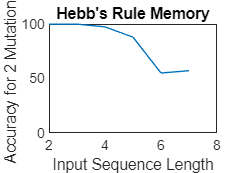

x = [2, 3, 4, 5, 6, 7];
plot(x, h2_hebb);
ylim([0 100]);
title("Hebb's Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 2 Mutations'); 
hold off

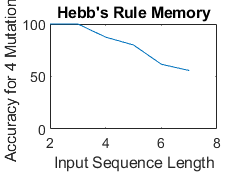

plot(x, h4_hebb);
ylim([0 100]);
title("Hebb's Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 4 Mutations'); 
hold off

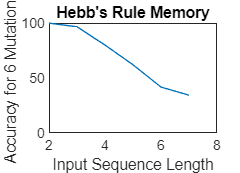

plot(x, h6_hebb);
ylim([0 100]);
title("Hebb's Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 6 Mutations'); 
hold off

**Repeating the Experiment using Pseudo-inverse Rule (II):**

We will now repeat the exact same process using the Pseudo-inverse rule. In order to facilitate the process, a helper function called 'pseudo_inverse' is created that returns the weights of a network trained on list of input patterns using Pseudo-inverse Rule:

% weights for zero and one
weights = pseudo_inverse(patterns(:,:,1:2));
% feed an input into the network to verify the results
output = hardlims(weights*reshape(zero, [30, 1]));
imshow(-1*reshape(output, [6, 5]), [], 'InitialMagnification', 1000);

And now the main loop of the experiment:

% Keep three histories, for 2, 4 and 6 mutations each.
h2_pinv = [];
h4_pinv = [];
h6_pinv = [];
num_mutations = [2, 4, 6];
% for [0, 1] through [0, 1, ..., 6]
for i=2:7
    train_data = patterns(:,:,1:i);
    weights = pseudo_inverse(train_data);
    % for a 2, 4 and 6 mutations
    for nm=num_mutations
        passes = 0;
        total = 10*size(train_data, 3);
        % perform 10 experiments, i.e., mutate 'nm' pixels from each input
        % pattern, then feed it into the network and compare the output
        % with the original data.
        for j=1:10
            % for each input pattern
            for l=1:size(train_data, 3)
                % do mutation
                test = mutate(nm, squeeze(train_data(:,:,l)));
                % calculate output
                output = hardlims(weights*reshape(test, [30, 1]));
                % reshape target into a [30, 1] vector
                target = reshape(train_data(:,:,l), [30, 1]);
                % compare target and output
                if isequal(target, output)
                    passes = passes + 1;
                end
            end
        end
        % append the accuracy percentages to the histories
        if nm == 2
            h2_pinv = [h2_pinv (100*passes)/total];
        elseif nm == 4
            h4_pinv = [h4_pinv (100*passes)/total];
        else
            h6_pinv = [h6_pinv (100*passes)/total];
        end
    end
end

We may now plot the results of our experiment with the Hebb Rule:

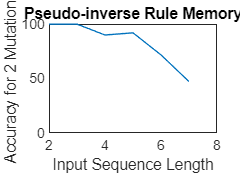

x = [2, 3, 4, 5, 6, 7];
plot(x, h2_pinv);
ylim([0 100]);
title("Pseudo-inverse Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 2 Mutations'); 
hold off

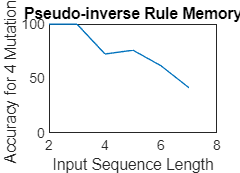

plot(x, h4_pinv);
ylim([0 100]);
title("Pseudo-inverse Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 4 Mutations'); 
hold off

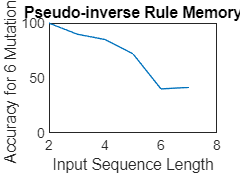

plot(x, h6_pinv);
ylim([0 100]);
title("Pseudo-inverse Rule Memory");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 6 Mutations'); 
hold off

**Cross-referencing the Results (I & II)**

We may now draw both graphs in one plot to see which algorithm performs better:

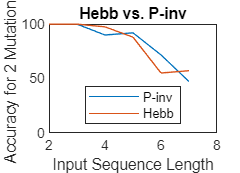

x = [2, 3, 4, 5, 6, 7];
plot(x, h2_pinv, x, h2_hebb);
ylim([0 100]);
title("Hebb vs. P-inv");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 2 Mutations');
legend('P-inv', 'Hebb', 'location', 'best');
hold off

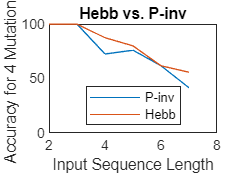

x = [2, 3, 4, 5, 6, 7];
plot(x, h4_pinv, x, h4_hebb);
ylim([0 100]);
title("Hebb vs. P-inv");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 4 Mutations');
legend('P-inv', 'Hebb', 'location', 'best');
hold off

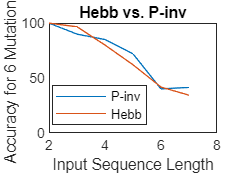

x = [2, 3, 4, 5, 6, 7];
plot(x, h6_pinv, x, h6_hebb);
ylim([0 100]);
title("Hebb vs. P-inv");
xlabel('Input Sequence Length'); 
ylabel('Accuracy for 6 Mutations'); 
legend('P-inv', 'Hebb', 'location', 'best');
hold off

The results yield no clear winner and both algorithm seem to be performing within the same range of accuracy. However it seems that Hebb's Rule is less robust against further mutations than Pseudo-inverse rule.